# ESERCIZIO 39

FRF-measurement using a noise excitation and a Hanning window

## FRF

Questo esercizio è legato al capitolo 3, del *Mastering System Identification in 100 Exercise,* nel quale viene studiato come misurare FRF, Frequency Response Function (funzione di risposta in frequenza) di un sistema lineare dinamico. 

**Nello specifico esericizio 39, viene affrontato il problema delle perdite, o del leakage, L'impatto dell'effetto di leakage può essere ridotto attraverso l'utilizzo di finestre,** ovvero moltiplicando i dati con una finestra nel dominio del tempo. L'idea di base è quella di utilizzare una valutazione pesata dei dati che vada a zero sia all'inizio che alla fine della finestra. Una finestra di questo tipo molto conosciuta è sicuramente** la finestra di Hanning**, che nel presente esercizio **sarà confrontata con la più standard finestra Rettangolare**.

Cos'è una **finestra**? **Le finestre sono funzioni matematiche** utilizzate nell'analisi dei segnali per modificare l'andamento di un segnale nel tempo o nello spazio. Vengono spesso utilizzate per **ridurre gli effetti indesiderati dell'analisi dei segnali**, come le distorsioni causate dai bordi del segnale. 

L'**effetto di leakage **(o perdita) è un fenomeno indesiderato che si verifica quando si analizza lo spettro di un segnale discreto tramite la trasformata di Fourier o altre tecniche simili. L**a correttezza di calcolo del segnale con FFT richiede la perfetta  ripetitività del segnale in un determinato intervallo di tempo.** In questo caso il risultato del calcolo FFT di questa tipologia di segnali non dà luogo ad errori.** Se invece i segnali sottoposti al calcolo FFT** presentano delle  discontinuità o semplicemente** non possono essere considerati ripetitivi  all’interno di un determinato intervallo di tempo** **allora in questi casi il calcolo con FFT da luogo ad errori**. Ciò si traduce nella generazione di frequenze che non rappresentano  correttamente lo spettro del segnale che risulta così deformato  dall’inserimento di queste indesiderate componenti aggiuntive di  frequenze. **Questo fenomeno viene definito con il termine “leakage”.**

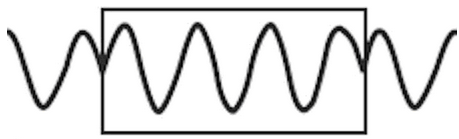     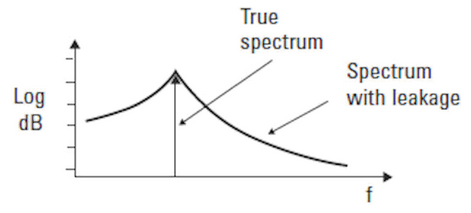

                        Dominio del tempo                                                  Dominio delle Frequenze

la **Finestra Rettangolare**: è la finestra più semplice e consiste in una funzione costante uguale a 1 all'interno del periodo di analisi e zero al di fuori di esso. Matematicamente, viene definita come:

w[n] = 1, se 0 ≤ n < N                                                        w[n] = 0, altrimenti

dove w[n] rappresenta il valore della finestra al tempo discreto n ed N è la lunghezza della finestra (in numero di campioni).

**La finestra rettangolare non apporta alcuna modifica al segnale originale**. Quando applicata a un segnale, semplicemente seleziona il periodo di analisi senza influenzarne l'andamento. Tuttavia, presenta alcuni svantaggi, come una risoluzione spettrale limitata e lobature laterali pronunciate.

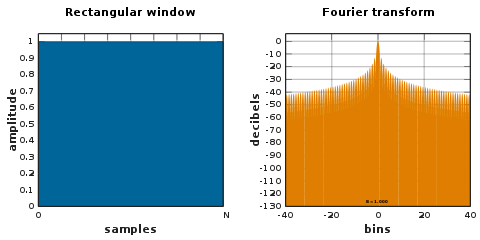

La** Finestra di Hanning**: è una finestra più avanzata che offre una migliore risoluzione spettrale rispetto alla finestra rettangolare. Ha una forma leggermente curva, che riduce le lobature laterali e fornisce una migliore attenuazione dei picchi spettrali. Matematicamente, la finestra di Hanning è definita come: 

w[n] = 0.5 * (1 - cos(2πn/(N-1))), se 0 ≤ n < N                 w[n] = 0, altrimenti

dove w[n] rappresenta il valore della finestra al tempo discreto n ed N è la lunghezza della finestra. 

**La finestra di Hanning moltiplica ogni campione del segnale originale per un fattore che dipende dalla sua posizione all'interno della finestra. Ciò porta a un graduale attenuamento ai bordi del segnale e riduce le lobature laterali nel dominio delle frequenze.** Questo può portare a una migliore risoluzione spettrale e a una maggiore precisione nelle misure della FRF.

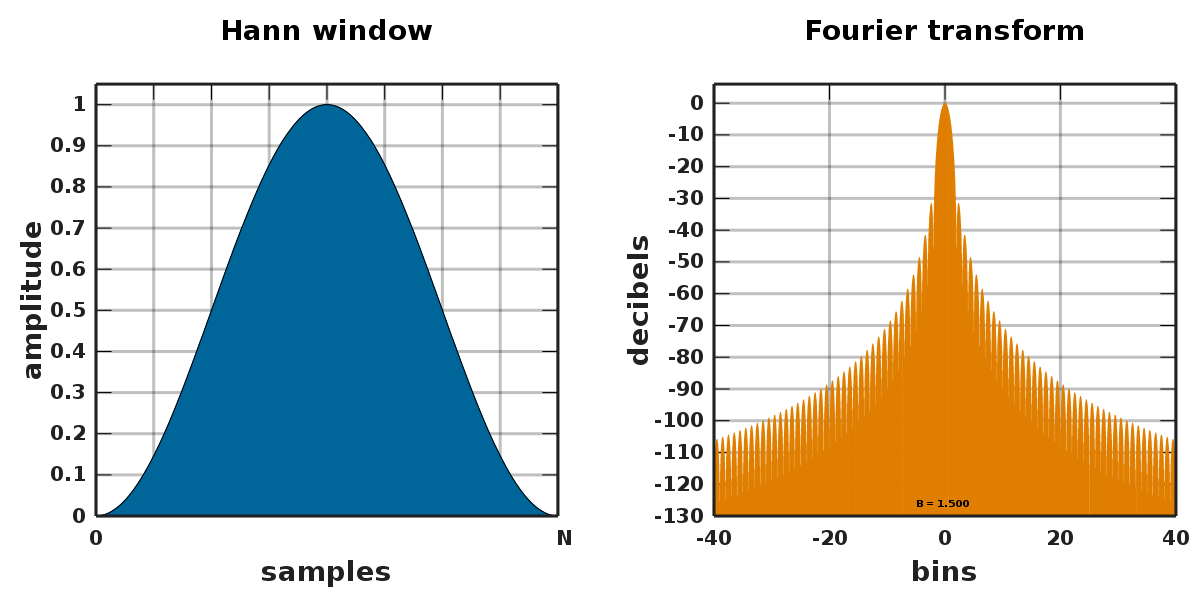

**Confronto tra la finestra rettangolare (R) e la finestra di Hanning (W) dato un segnale sinusoidale periodico**

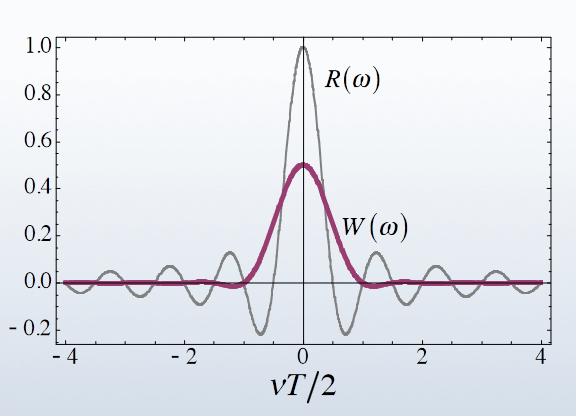

- Il picco centrale di W è più largo di quello di R;

- I lobi laterali di W decadono molto più velocemente di quelli di R;

- Il valore di picco di W è la metà di quello di R.

Queste proprietà della finestra di Hanning implicano che:

- La risoluzione in frequenza della finestra è un po’ ridotta;

- Lo spectral leakage è molto inferiore;

- Quando si applica una finestra si deve compensare la riduzione di ampiezza.

% Part 1
%
% Compare rectangular and Hanning window for number of averages
% and a fixed block length


clear all                       % Pulizia del Workspace
clc                             % Pulizia Command Window
close all                       % Chiusura finestre

I blocchi sono una porzione di dati consecutivi presi da un segnale. È una tecnica comune per:

- semplificare la gestione dei dati

- focalizzarsi su segmenti specifici 

- ridurre la complessità computazionale

%% Definizione delle variabili (parametri e dimensioni dei dati):
%
% i Blocchi: una porzione di dati consecutivi presi da un segnale
%
% MAll: È un vettore che contiene i numeri di blocchi da elaborare.
MAll=[1 4 16 256 1024 4096];    
% Questo vettore verrà utilizzato per calcolare le diverse stime spettrali
% ottenute variando il numero di blocchi. 

% M: Viene assegnato alla variabile M il valore massimo presente nel vettore 
% MAll. 
% Quindi, M conterrà il valore 4096
M=max(MAll);   

% Il numero di campioni:
%
% NPeriod: Rappresenta il numero di punti dati per blocco o periodo. 
% Indica la lunghezza del blocco di dati utilizzato per le analisi 
% successive. 
% Ex-->i segnali di ingresso (u) e di uscita (y) 
% vengono suddivisi in blocchi di lunghezza NPeriod.
NPeriod=1024;      

% N: È il numero totale di punti dati nell'intera misurazione, calcolato 
% moltiplicando NPeriod per M. 
% Ex --> se NPeriod è 1024 e M è 4096, allora N sarà 4.194.304
N=NPeriod*M;                                                                %%%%PERCHE NON MALL?

% la frequenza di campionamento:
%
% fs: È la frequenza di campionamento, cioè il numero di campioni acquisiti 
% al secondo. 

NPeriod = 1024

% Ex --> se fs è 128, significa che vengono acquisiti 128 campioni 
% al secondo.
fs=128;                                      % Hz

% Ampiezza del segnale:
%
% Ampl: Rappresenta l'ampiezza del segnale multi-sine, misurata come valore 
% RMS (Root Mean Square). 
Ampl=1;
% Stiamo parlando del valore efficace, cioè il valore che avrebbe un segnale
% costante di pari potenza

% La frequenza massima per l'input:

fs = 128

%
% fGen: Rappresenta la larghezza di banda dell'eccitazione, cioè la banda
% di frequenze dell'input generato. 
%
% Ex --> se fs è 128, allora fGen sarà 0.3 * 128 = 38.4. Questo significa 
% che il segnale sarà composto da componenti armoniche con frequenze 

Ampl = 1

% comprese tra 0 Hz e 38.4 Hz.
fGen=0.3*fs                                
%Se fGen fosse impostato a un valore superiore a fs, ciò potrebbe portare 
% a problemi di aliasing. Inoltre, impostando fGen in modo proporzionale 
% a fs, è possibile mantenere una relazione coerente tra le frequenze 
% delle componenti armoniche dell'input generato e la capacità di 
% risoluzione dello spettro ottenuto tramite l'analisi in frequenza
 
% Transitori:
%
% NTrans: Indica il numero di punti dati da eliminare per eliminare 
% gli effetti transitori della simulazione. 

fGen = 38.4000

NTrans=1024;                

% Istanti di campionamento in un periodo:
%
t=[0:NPeriod-1]/fs;             % Time vector of ONE PERIOD: Crea un vettore t che 

NTrans = 1024

                                % rappresenta una sequenza di valori di tempo che
                                % copre un singolo ciclo o periodo del segnale. 
                                % 
                                % Ex --> t avrà 1024 punti equidistanti nel 
                                % tempo, che rappresentano un periodo di 8sec 
                                % --> (1024/128 = 8) --> Sono gli istanti in 
                                % cui sono stati catturati i singoli campioni 
                                % contenuti in 8sec con fs a 128Hz

% Istanti di campionamento nell'intera sequenza:
%
tAll=[0:N-1]/fs;                % Time vector of FULL SEQUENCE: 
                                % Ex --> se NPeriod è 1024, M è 4 e fs è 128, il 
                                % vettore tAll avrà 4096 punti equidistanti nel 
                                % tempo, che rappresentano un'intera sequenza di 
                                % 32sec 
                                % --> (4096/128 = 32). -->Sono gli istanti in 
                                % cui sono stati catturati i singoli campioni 
                                % contenuti in 32sec con fs a 128Hz
                                

### **Cosa mostriamo?**

Quando si esegue l'analisi spettrale dei segnali tramite la trasformata di Fourier, si ottiene uno spettro che contiene tutte le frequenze possibili del segnale. Tuttavia, in alcuni casi è necessario visualizzare** solo un sottoinsieme di queste frequenze**, **in particolare alla metà (per simmetria)**.

Nell'analisi spettrale di un segnale reale, lo spettro ha una proprietà di simmetria. Le frequenze negative sono in realtà un duplicato delle frequenze positive, ma con segno negativo. Pertanto, **la visualizzazione delle sole frequenze positive fornisce un'informazione completa sullo spettro del segnale.**

*Un esempio semplice: *

*Supponiamo che Lines sia [1,2,3,4], calcolando Lines-1 [0, 1, 2, 3]. Quindi dividendo per NPerdiod (ad esempio 100), otteniamo [0, 0.01, 0.02, 0.03], che moltiplicando per fs (ad esempio 1000Hz), otteniamo [0 ,10, 20, 30] Hz. che rappresentano le frequenze corrispondenti alle linee selezionate nel dominio delle frequenze reali. *


% Scegliamo le frequenze di interesse:
%
Lines=[1:NPeriod/2];            % Select the lines to be plotted: Questa riga crea un 
                                % vettore Lines che rappresenta le linee (o frequenze) 
                                % da visualizzare nel grafico. 
                                %
                                % Ex --> se NPeriod è 1024, il vettore Lines avrà le 
                                % frequenze da 1 a 512. 
                                % Ma questo è un vettore di elementi e non
                                % fqz!

% Riportiamo le linee alle corrispettive frequenze inm Hz:
%
f=[Lines-1]'/NPeriod*fs;        % Frequency vector: Questa riga crea un vettore f che 
                                % rappresenta le frequenze di interesse. 
                                %
                                % Ex --> se NPeriod è 1024 e fs è 128, il vettore f 
                                % rappresenterà le frequenze da 0 a 64 Hz 
                                % --> (512/1024*128 = 64)


## Filtro di Chebyshev e filtro di Butterworth

#### Il **Filtro di Chebyshev**

Il filtro di Chebyshev è un tipo di filtro utilizzato per modificare o  eliminare determinate componenti di frequenza in un segnale. Il suo scopo principale è quello di **selezionare una banda di frequenza  specifica (banda di passaggio) e attenuare le frequenze al di fuori di  questa banda (banda di stop).** In particolare, vengono generati i coefficienti `b` e `a` per un filtro di Chebyshev di secondo ordine utilizzando la funzione `cheby1`.

I coefficienti `b` e `a` ottenuti rappresentano ***i parametri del filtro di Chebyshev*** e vengono utilizzati successivamente per applicare il filtro al segnale.

**L'effetto del filtro di Chebyshev è quello di modificare lo spettro del segnale, attenuando alcune frequenze specifiche e lasciando passare altre.** Ciò consente di ottenere una risposta desiderata del sistema nel dominio delle frequenze.

**L'uso del filtro di Chebyshev in questo caso consente di filtrare il segnale di ingresso **`u`** prima di applicarlo al sistema e ottenere la risposta **`y`**. Questo aiuta a ridurre l'effetto di eventuali rumori o componenti indesiderate presenti nel segnale di ingresso.**

% Filtro di Chebyshev:
%
[b,a]=cheby1(2,10,0.2);         % test system: Questa riga crea i coefficienti b e a per 
                                % un filtro di Chebyshev di tipo uno. 
                                % In questo caso, vengono specificati:
                                %
                                % + Grado del filtro = 2;
                                % + Ampiezza massima nella banda di
                                %   passaggio (Attenuazione) = 10dB
                                % + Frequenza di taglio (norm.) = 0.2
                            
                        

#### Il **Filtro di Butterworth**

Il Filtro di Butterworth è un tipo di filtro che viene utilizzato per modificare lo spettro di un segnale in modo da attenuare o eliminare determinate componenti di frequenza indesiderate. **A differenza del filtro di Chebyshev, il filtro di Butterworth offre una risposta di attenuazione più uniforme nel passaggio da una banda di frequenza all'altra.**

In questo caso, il filtro di Butterworth viene utilizzato per generare un segnale di eccitazione colorato (colored random excitation) utilizzando i coefficienti `bGen` e `aGen`. Questo segnale di eccitazione viene successivamente utilizzato come input nel sistema di test.

**Il filtro di Butterworth, in questo caso, viene applicato al segnale di ingresso bianco (white noise sequence) **`u`** per ottenere un segnale di ingresso colorato (colored input noise).** L'applicazione del filtro di Butterworth consente di modulare lo spettro del segnale di ingresso (rumore bianco generato con randn) in base alle specifiche dei coefficienti `bGen` e `aGen`, fornendo un segnale di eccitazione con una determinata distribuzione di energia nelle frequenze.

**"Colored" perché il segnale di uscita dal filtro ha subito una modifica spettrale e non presenta più una distribuzione di potenza uniforme su tutte le frequenze come per il rumore bianco.**

**L'utilizzo di un segnale colorato generato da un filtro specifico, come il filtro di Butterworth, consente di ottenere una distribuzione spettrale controllata e concentrata in una specifica banda di frequenza.**

Nell'esercizio, viene applicato un filtro di Butterworth per **generare un segnale colorato con una distribuzione spettrale specifica centrata attorno alla frequenza di banda desiderata, definita come fGen (0.3*fs). Ciò consente di ottenere un segnale di ingresso che è maggiormente concentrato nella banda di interesse**, fornendo quindi una maggiore precisione e risoluzione nella misurazione della risposta del sistema in quella banda di frequenza.

% Filtro di Butterworth:
%                                
[bGen,aGen]=butter(2,fGen/fs*2); % generator filter to generate colored random excitation:
                                % Questa riga crea i coefficienti bGen e aGen per un 
                                % filtro di Butterworth di secondo ordine. Il filtro di 
                                % Butterworth è utilizzato per generare un segnale di 
                                % eccitazione casuale colorato. In questo caso, viene 
                                % specificato il grado del filtro (2) e la frequenza di 
                                % taglio normalizzata fGen/fs*2. 

% Generazione del segnale di eccitazione:
%
u=randn(N+NTrans,1)*Ampl;       % generate white noise sequence: Viene generata una 
                                % sequenza di rumore bianco u di lunghezza 
                                % (N + NTrans) = 4195328.
                                % Il vettore u viene moltiplicato per l'ampiezza 
                                % desiderata Ampl per controllare l'energia del segnale.
% Applico filtro di Butterwoth
%
u=filter(bGen,aGen,u);          % colored input noise:  viene applicato il filtro di 
                                % Butterworth definito dai coefficienti bGen e aGen al 
                                % segnale u, ottenendo così un segnale di ingresso 
                                % colorato (colored input noise). 

% Risposta del sistema, con filtro di Chebyshev:
%
y=filter(b,a,u);                % response of the system: Il segnale di ingresso colorato
                                % u viene applicato al sistema utilizzando la funzione 
                                % filter, che restituisce la risposta del sistema nel 
                                % vettore y. 
                                % Il sistema è descritto dai coefficienti del filtro "b" 
                                % e "a", che sono stati definiti in precedenza come il 
                                % filtro di Chebyshev.
% Elimino i transitori:
%
y(1:NTrans)=[];u(1:NTrans)=[];  % eliminate transients: Vengono eliminati i punti dati 
                                % iniziali NTrans sia dal segnale di ingresso u che dalla 
                                % risposta del sistema y. Questo viene fatto per eliminare 
                                % gli effetti transitori presenti nel segnale, ottenendo 
                                % così le componenti stazionarie e riducendo l'influenza 
                                % degli effetti iniziali non rappresentativi del sistema.

% Elaborazione dei dati:

% processing: steady state and transient:
% I vettori y e u vengono ridimensionati in modo da avere NPeriod punti dati per colonna, 
% dove NPeriod rappresenta il numero di punti dati per blocco o periodo. Questo viene 
% fatto utilizzando la funzione reshape, che organizza i dati in matrici di dimensioni 
% specificate.

y=reshape(y,NPeriod,M);         % put each period in a collumn: y viene organizzato come 
                                % una matrice: [NPeriod x M]. Ogni colonna di y rappresenta 
                                % un periodo di lunghezza NPeriod
u=reshape(u,NPeriod,M);         % u viene organizzato come una matrice NPeriod x M, 
                                % corrispondente alla forma di y

## Hanning Window

Abbiamo bisogno di ripetere la finestra:

- Prendiamo un sottorecord specifico di "y" di lunghezza "NPeriod" e chiamiamolo "y_sub".

- Generiamo la finestra di Hanning di lunghezza "NPeriod" e chiamiamola "w_hann". Questa finestra avrà valori compresi tra 0 e 1, con i valori più alti al centro della finestra e i valori più bassi ai bordi.

- Moltiplichiamo elemento per elemento "y_sub" e "w_hann" per applicare la finestra di Hanning al sottorecord. Chiamiamo il risultato "y_sub_hann".

- Ripetiamo questi passaggi per tutti gli altri sottorecord di "y".

Alla fine di questo processo, otterremo una versione "y_hann" in cui ciascun sottorecord è stato moltiplicato per la finestra di Hanning corrispondente. 

% Spectral analysis process: Hanning window -> Creazione finestra di Hanning:
%
w=hanning(NPeriod,'periodic');      % the Hanning window: Viene creata la finestra di 
                                    % Hanning con lunghezza pari a NPeriod.  
                                    % La versione 'periodic' della finestra di Hanning 
                                    % crea una finestra simmetrica che si ripete 
                                    % periodicamente.

% wAll è una matrice che contiene ripetizioni della finestra di Hanning per ogni 
% sottorecord. Viene utilizzata per applicare la finestra di Hanning simultaneamente 
% a tutti i sottorecord di "y"
%
wAll=kron(w(:),ones(1,M));          % repeated window to process all sub-records at once: 
                                    % La finestra di Hanning viene ripetuta M volte per 
                                    % processare tutti i sottoblocchi contemporaneamente. 
                                    % Questo viene fatto utilizzando la funzione kron(*) 
                                    % per creare una matrice in cui la finestra di Hanning 
                                    % viene replicata in colonne M volte.

% (*) --> La funzione kron() esegue il prodotto di Kronecker tra due array. In altre 
% parole, crea una matrice in cui ogni elemento dell'array di sinistra viene moltiplicato 
% per tutti gli elementi dell'array di destra. 
% In questo caso, wAll=kron(w(:),ones(1,M)); viene utilizzata per creare una matrice wAll 
% che rappresenta la finestra di Hanning ripetuta per elaborare contemporaneamente tutti 
% i sotto-record. Utilizzando w(:) si ottiene un vettore colonna che rappresenta la 
% finestra di Hanning. 
% kron(w(:),ones(1,M)) crea una matrice in cui il vettore colonna w(:) viene replicato M 
% volte lungo la dimensione delle colonne utilizzando ones(1,M)

Prima di procedere è necessario un chiarimento:

*Nel dominio del tempo, l'energia di un segnale è rappresentata dalla  somma dei quadrati dei campioni del segnale. Nel dominio della  frequenza, l'energia è distribuita tra le diverse componenti di  frequenza presenti nel segnale.*

A seguito della trasformata di Fourier si rende necessaria una normalizzazione, senza la quale l'ampiezza degli spettri nel dominio della  frequenza potrebbe essere erroneamente influenzata dalla lunghezza del  blocco, portando a una sovrastima o sottostima dell'energia delle  componenti di frequenza. **La normalizzazione assicura che l'ampiezza  degli spettri rifletta correttamente l'energia relativa delle componenti di frequenza nel segnale originale, indipendentemente dalla lunghezza  del blocco** o della sequenza di dati utilizzata.

% Rectangular Window:

Y=fft(y)/sqrt(NPeriod/2);           % spectral analysis, block per block using rectangular 
                                    % window: 
                                    % 1. Viene calcolata la trasformata di Fourier 
                                    % veloce (FFT) del segnale y. 
                                    % 2. La divisione per sqrt(NPeriod/2) è un fattore 
                                    % di normalizzazione. Il diviso 2 è
                                    % legato all'assenza di coefficienti
                                    % per le frequenze negative, in quanto
                                    % in simmetria.

Y=Y(Lines,:);                       % Viene selezionata solo la porzione delle frequenze 
                                    % specificate dal vettore Lines. 

U=fft(u)/sqrt(NPeriod/2);           % Viene calcolata la FFT del segnale di eccitazione u. 
                                    % Anche in questo caso, viene applicata la 
                                    % normalizzazione. 

U=U(Lines,:);                       % Viene selezionata solo la porzione delle frequenze 
                                    % specificate dal vettore Lines.

% Hanning Window
% La finestra di Hanning deve essere applicata prima della trasformata di Fourier (FFT). 
% Questo perché la finestra di Hanning è una finestra di smoothing nel dominio del 
% tempo che viene utilizzata per ridurre l'effetto delle discontinuità ai bordi del 
% segnale durante la trasformata di Fourier.

% Se x = [1, 2, 3, 4, 5] 
% con Hanning -> 
% >> w = [0.08, 0.54, 1.0, 0.54, 0.08]
% >> x_hann = [1 * 0.08, 2 * 0.54, 3 * 1.0, 4 * 0.54, 5 * 0.08] 
% >>        = [0.08, 1.08, 3.0, 2.16, 0.4]
% FFT: X = [2.5, -1.5 - j0.87, 0.0, -1.5 + j0.87, -1.5]
%
% con Rettangolare ->
% >> x_rett = x
% FFT: X = [15, -5 + j3.44, 0, -5 - j3.44, -5]

YHann=fft(y.*wAll)/sqrt(NPeriod/2); % spectral analysis, block per block using Hanning 
                                    % window: Viene calcolata la FFT del segnale y 
                                    % moltiplicato per la finestra di Hanning wAll. Anche 
                                    % in questo caso, viene applicata la normalizzazione. 

YHann=YHann(Lines,:);               % Vengono selezionate solo le frequenze indicate da 
                                    % Lines.

UHann=fft(u.*wAll)/sqrt(NPeriod/2); % Viene calcolata la FFT del segnale di eccitazione u 
                                    % moltiplicato per la finestra di Hanning wAll. Anche 
                                    % in questo caso, viene applicata la normalizzazione.

UHann=UHann(Lines,:);               % Vengono selezionate solo le frequenze indicate da 
                                    % Lines

N.B.: Si vuole calcolare la trasformata di Fourier a blocchi dei segnali `y` e `u,` utilizzando la funzione `fft`. Tuttavia, **poiché nessuna finestra specifica viene applicata** prima del  calcolo della trasformata, **si sta effettivamente utilizzando  implicitamente una finestra rettangolare.**

Tuttavia, successivamente nel codice, viene applicata esplicitamente la finestra di Hanning per l'analisi spettrale. In questo caso, la finestra di Hanning `wAll` viene moltiplicata per i segnali `y` e `u` prima del calcolo della trasformata di Fourier.

## **Schema a Blocchi Semplificativo**

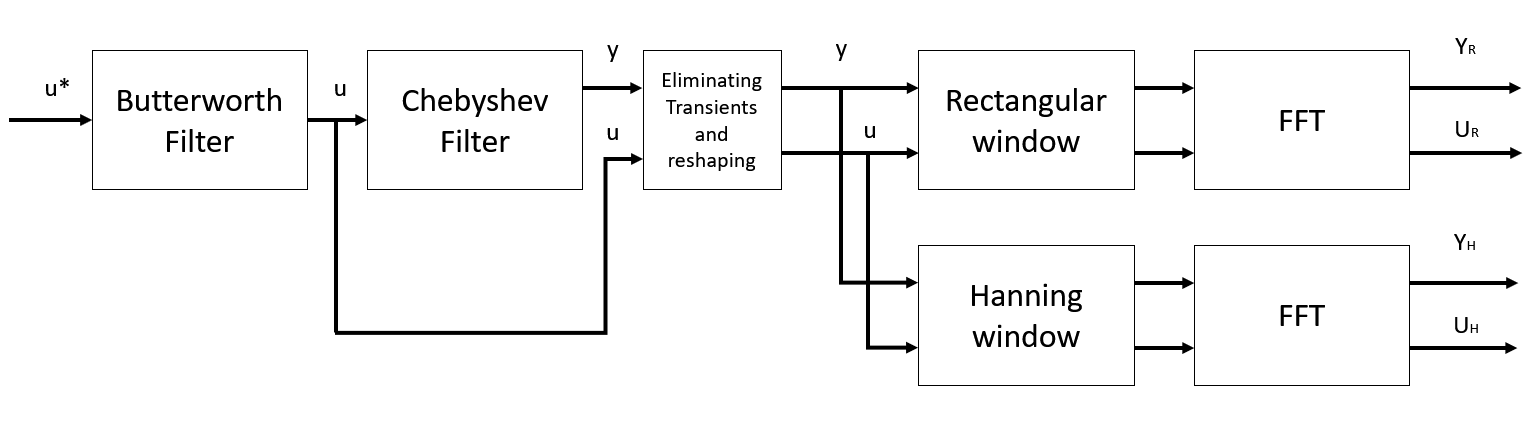

**Per ottenere una stima accurata della FRF, è necessario calcolare la PSD (Power Spectral Density) dei segnali di  ingresso e uscita e quindi calcolare il rapporto tra le due PSD**. Calcolare direttamente il rapporto tra Y e U senza considerare le PSD potrebbe portare a risultati distorti, in quanto non tiene conto della distribuzione di potenza dei segnali a diverse frequenze.

(**)--> **La stima della densità spettrale di potenza fornisce una rappresentazione del segnale in termini di come l'energia del segnale è distribuita in diverse frequenze.** Stimarla consente di identificare le frequenze dominanti o rilevanti nel segnale e di valutare l'ampiezza dell'energia in corrispondenza di queste frequenze.

**La media viene calcolata per ottenere una stima statistica più accurata della potenza del segnale. **Calcolando la media dei quadrati dei campioni, si tiene conto sia degli ampi picchi del segnale che delle componenti di rumore. Inoltre, il calcolo della media riduce l'effetto dell'aliasing e del rumore nel segnale, fornendo una stima più stabile e affidabile della potenza.

**La stima della densità spettrale di potenza viene utilizzata anche per calcolare le funzioni di risposta in frequenza (FRF)** del sistema, dove la FRF rappresenta il rapporto tra la risposta del sistema y e il segnale di ingresso u in termini di amplificazione e fase a diverse frequenze. 

for k=length(MAll):-1:1                         % loop over number of blocks : Questo 
                                                % ciclo viene utilizzato per calcolare 
                                                % diverse stime spettrali al variare 
                                                % del numero di blocchi di dati.

% RETTANGOLARE:

    UU(:,k)=mean(abs(U(:,1:MAll(k))).^2,2);     % estimate SUU Rectangular: 
    %
    % Calcola la MEDIA dei QUADRATI del MODULO del segnale U per i primi MAll(k) campioni 
    % di ciascuna colonna. Questo calcolo rappresenta una stima della densità spettrale 
    % di potenza PSD del segnale di ingresso u ed è indicata come SUU rectangular (**)

    YU(:,k)=mean(Y(:,1:MAll(k)).*conj(U(:,1:MAll(k))),2);   % estimate SYU:
    %
    % Calcola la media del prodotto tra il segnale Y (risposta del sistema) e il complesso 
    % coniugato del segnale U per i primi MAll(k) campioni di ciascuna colonna. 
    % Questo calcolo rappresenta una stima della densità spettrale di coerenza tra il 
    % segnale di ingresso u e la risposta del sistema y ed è indicata come SYU.

    % FRF Rectangular:
    %
    G(:,k)=YU(:,k)./UU(:,k);                                 
    % 
    % Calcola il rapporto tra le stime SYU e SUU per ottenere la funzione di risposta 
    % in frequenza (FRF) del sistema. Questo calcolo restituisce una stima della 
    % risposta del sistema in termini di amplificazione e fase per diverse frequenze 
    % di interesse.

% HANNINAG

    UUHann(:,k)=mean(abs(UHann(:,1:MAll(k))).^2,2);         % estimate SUU Hanning: Esegue 
                                                            % una stima simile a UU 
                                                            % utilizzando i segnali UHann, 
                                                            % che sono stati moltiplicati 
                                                            % per la finestra di Hanning wAll. 
                                                            % Questo calcolo rappresenta 
                                                            % una stima della densità 
                                                            % spettrale di potenza del 
                                                            % segnale di ingresso u 
                                                            % utilizzando la finestra di 
                                                            % Hanning ed è indicata come 
                                                            % SUU Hanning

    YUHann(:,k)=mean(YHann(:,1:MAll(k)).*conj(UHann(:,1:MAll(k))),2);   % estimate SYU:  
    % Esegue una stima simile a YU utilizzando i segnali YHann e UHann moltiplicati per la 
    % finestra di Hanning. Questo calcolo rappresenta una stima della densità spettrale di 
    % coerenza tra il segnale di ingresso u e la risposta del sistema y utilizzando la 
    % finestra di Hanning ed è indicata come SYU Hanning.

    % FRF Hanning:
    %
    GHann(:,k)=YUHann(:,k)./UUHann(:,k);                     
    % Calcola il rapporto tra le stime SYU Hanning e SUU Hanning per ottenere la FRF del 
    % sistema utilizzando la finestra di Hanning.
end
    

Di seguito è mostrata la rappresentazione grafica dei risultati dell'analisi spettrale dei dati. In particolare, il codice mostra i  grafici delle funzioni di risposta in frequenza (FRF) per un numero crescente di blocchi mediati.

% plot the results: FRF for increasing number of averaged blocks
FigNum=1 

FigNum = 1

figure(FigNum)   % using the Hanning window

G0=freqz(b,a,f*2*pi/fs);
clf
subplot(2,3,1)
plot(f,db(G0),'k',f,db(G(:,1)-G0),'.b',f,db(GHann(:,1)-G0),'.k'),title('M=1')
ylabel('Amplitude (dB)')
axis([0 60 -80 0])
DG_SetTraceTint(30,2,FigNum,1)
DG_SetTraceWidth(2,'*',FigNum,1)
DG_SetFontSize(12)

subplot(2,3,2)
plot(f,db(G0),'k',f,db(G(:,2)-G0),'.b',f,db(GHann(:,2)-G0),'.k'),title('M=4')
axis([0 60 -80 0])
DG_SetTraceTint(30,2,FigNum,2)
DG_SetTraceWidth(2,'*',FigNum,2)
DG_SetFontSize(12)

subplot(2,3,3)
plot(f,db(G0),'k',f,db(G(:,3)-G0),'.b',f,db(GHann(:,3)-G0),'.k'),title('M=16')

axis([0 60 -80 0])
DG_SetTraceTint(30,2,FigNum,3)
DG_SetTraceWidth(2,'*',FigNum,3)
DG_SetFontSize(12)

subplot(2,3,4)

plot(f,db(G0),'k',f,db(G(:,4)-G0),'.b',f,db(GHann(:,4)-G0),'.k'),title('M=256')
axis([0 60 -80 0])
ylabel('Amplitude (dB)')
xlabel('f (Hz)')
DG_SetTraceTint(30,2,FigNum,4)
DG_SetTraceWidth(2,'*',FigNum,4)
DG_SetFontSize(12)

subplot(2,3,5)

plot(f,db(G0),'k',f,db(G(:,5)-G0),'.b',f,db(GHann(:,5)-G0),'.k'),title('M=1024')
xlabel('f (Hz)')

axis([0 60 -80 0])
DG_SetTraceTint(30,2,FigNum,5)
DG_SetTraceWidth(2,'*',FigNum,5)
DG_SetFontSize(12)

subplot(2,3,6)

plot(f,db(G0),'k',f,db(G(:,6)-G0),'.b',f,db(GHann(:,6)-G0),'.k'),title('M=4096')
xlabel('f (Hz)')
axis([0 60 -80 0])
DG_SetTraceTint(30,2,FigNum,6)
DG_SetTraceWidth(2,'*',FigNum,6)
DG_SetFontSize(12)


%DG_Init4PDF(gcf, 4.5);        % fixing the size, half standard height
%DG_MakePDF('FigExcitation307Hann1.pdf', gcf); 
    
    

Sono stati plottati i grafici delle funzioni di risposta in frequenza (FRF) per diverse configurazioni di blocchi mediati, relativamente alla variazione del numero di blocchi utilizzati per calcolare la media delle misure spettrali.** La FRF rappresenta la relazione tra l'ingresso e l'uscita di un sistema in termini delle rispettive componenti in frequenza.**

La figura ha una griglia di 2 righe per 3 colonne, per un totale di 6 subplot. **Ogni subplot rappresenta una diversa configurazione di blocchi mediati, come indicato dal valore di **`M`, costituito da 6 elementi`.`

**Sull'asse delle ordinate di ciascun subplot viene mostrata l'ampiezza della differenza tra la FRF calcolata e la FRF teorica, espressa in decibel (dB). Questo fornisce un'indicazione della discrepanza tra la risposta del sistema stimata e quella teorica per diverse frequenze.** 

Nel grafico, **la linea nera rappresenta la FRF teorica del sistema (**`G0`**)**, calcolata utilizzando i coefficienti del filtro `b` e `a`. **I punti blu (**`'.b'`**) rappresentano la differenza tra la FRF calcolata con finestra rettangolare (**`G(:,k)`) e la FRF teorica (`G0`). Allo stesso modo, **i punti neri (**`'.k'`**) rappresentano la differenza tra la FRF calcolata con finestra di Hann (**`GHann(:,k)`**)** e la FRF teorica (`G0`).

**L'obiettivo di questa rappresentazione grafica è mostrare come l'aumento del numero di blocchi mediati influisca sulla precisione e sulla stabilità della stima della FRF**. **In particolare, ci si aspetta che all'aumentare di **`M`**, la differenza tra la FRF calcolata e la FRF teorica diminuisca**, indicando una migliore approssimazione della risposta del sistema.

Nel primo subplot con `M = 1`, viene calcolata la risposta in frequenza utilizzando un solo blocco di dati. Questo significa che  viene preso solo un segmento dei dati in ingresso per calcolare la  risposta in frequenza del sistema. Ci si aspetta che la stima della risposta in frequenza ottenuta con `M = 1` sia più soggetta a fluttuazioni e rumore rispetto alle stime ottenute  con un numero maggiore di blocchi mediati. In altre parole, la  precisione della stima potrebbe essere inferiore a causa della maggiore  variabilità nei dati di input. **Aumentando **`M`**, ovvero il numero di blocchi mediati, si tende a ridurre l'effetto del rumore e delle fluttuazioni casuali, ottenendo  stime più precise e stabili della risposta in frequenza.**

Nel secondo subplot, con `M = 4` si osservano le differenze tra la risposta in frequenza stimata e la risposta in  frequenza del sistema reale per due diverse finestre (rettangolare e di  Hanning) con un numero di blocchi mediati di 4. **Nel caso di **`M = 1`**, si utilizza solo un blocco di dati per stimare la risposta in frequenza, con **`M = 4`**, invece, si utilizzano quattro blocchi di dati per stimare la risposta in frequenza. Questo permette di ridurre il rumore e migliorare la precisione della stima**, come si osserva dal grafico infatti i punti tendono a disperdersi meno. Inoltre, l'applicazione della finestra ha un effetto meno marcato sulla stima, poiché i blocchi mediati possono mitigare l'impatto delle transizioni tra i blocchi. Infatti la stima della risposta in frequenza dovrebbe essere migliorata e le  differenze dovrebbero essere meno pronunciate rispetto alla  configurazione con un solo blocco mediato. CIOE' --> Quando si suddivide il segnale in blocchi per l'analisi spettrale, potrebbero verificarsi transizioni o discontinuità tra un blocco e l'altro. Queste transizioni possono introdurre artefatti o distorsioni nella stima della risposta in frequenza del sistema. Tuttavia, utilizzando più blocchi mediati insieme, le caratteristiche di transizione tra i blocchi si bilanciano e si attenuano reciprocamente. Ciò significa che gli effetti negativi delle transizioni tra i blocchi diventano meno evidenti e l'accuratezza della stima della risposta in frequenza viene migliorata.

Aumentando ancora il numero di blocchi mediati, per `M = 16` osserviamo un miglioramento nei plot soprattutto per il grafico a cui è associato l'uso della finestra di Hanning. Questo è facilmente spiegato dal fatto che **la finestra rettangolare è una finestra semplice che assegna un peso costante di valore 1 a tutti i campioni dell'intervallo temporale considerato**. Di conseguenza, quando viene applicata alla serie temporale, **la finestra rettangolare non introduce alcuna attenuazione o modulazione ai dati**. D'altra parte, **la finestra Hanning è una finestra a forma di coseno alzato, che assegna pesi maggiori ai campioni centrali e pesi minori ai campioni ai bordi**. **Questa finestra introduce una modulazione sinusoidale ai dati, che attenua i contributi ai bordi e migliora la risoluzione in frequenza**. Ciò significa che l**'uso della finestra Hanning può ridurre le  distorsioni spettrali e migliorare la precisione nella stima degli  spettri di potenza o delle risposte in frequenza.** Poiché si stanno mediando un numero maggiore di blocchi, si riduce  l'effetto delle variazioni locali e delle transizioni tra i blocchi. Ciò porta a una stima più stabile e coerente della risposta in frequenza  del sistema. Aumentando il numero di blocchi mediati (da M=1 a M=4 e successivamente a M=16), si osserva un miglioramento graduale nella precisione, nella  regolarità e nella stabilità della stima della risposta in frequenza del sistema.

Per il 4 subplot `M = 256``,`**si osserva una maggiore concentrazione dei punti neri rispetto a M=1 e M=4**. **Tuttavia, i punti neri non sono più vicini alla linea fissa (rappresentata da G0), questo indica che, nonostante la maggiore concentrazione dei punti, le  stime della FRF ottenute con M=256 utilizzando la finestra di Hanning  presentano un errore rispetto alla FRF di riferimento**. Per la finestra rettangolare, si osserva una situazione simile a M=1 e  M=4, con punti blu molto dispersi. Ciò indica che le stime della FRF  ottenute con la finestra rettangolare continuano a presentare un errore  significativo e un'alta variabilità rispetto alla FRF di riferimento. **In conclusione, l'aumento del numero di blocchi mediati (M=256) migliora la concentrazione dei punti neri con la finestra di Hanning, ma non  necessariamente riduce l'errore rispetto alla FRF di riferimento.**

Aumentando ancora il valore di `M`, con `M = 1024` ed `M = 4096`,  ciò che si osserva è una maggiore concentrazione dei punti, sia neri che blu, infatti come già osservato, **quando si aumenta M a valori più elevati come M = 256 o M = 1024, i  punti si concentrano maggiormente.  Ciò è dovuto all'effetto della mediazione dei blocchi, che riduce  l'effetto del rumore e delle fluttuazioni casuali presenti nei singoli  blocchi. **

% plot the results: FRF for increasing number of averaged blocks
FigNum=10 

FigNum = 10

figure(FigNum)   % using the Hanning window

G0=freqz(b,a,f*2*pi/fs);
clf
subplot(2,3,1)
plot(f,db(G0),'k',f,db(G(:,1)),'.b',f,db(GHann(:,1)),'.r'),title('M=1')
ylabel('Amplitude (dB)')
axis([0 60 -80 0])
DG_SetTraceTint(30,2,FigNum,1)
DG_SetTraceWidth(2,'*',FigNum,1)
DG_SetFontSize(12)

subplot(2,3,2)
plot(f,db(G0),'k',f,db(G(:,2)),'.b',f,db(GHann(:,2)),'.r'),title('M=4')
axis([0 60 -80 0])
DG_SetTraceTint(30,2,FigNum,2)
DG_SetTraceWidth(2,'*',FigNum,2)
DG_SetFontSize(12)

subplot(2,3,3)
plot(f,db(G0),'k',f,db(G(:,3)),'.b',f,db(GHann(:,3)),'.r'),title('M=16')

axis([0 60 -80 0])
DG_SetTraceTint(30,2,FigNum,3)
DG_SetTraceWidth(2,'*',FigNum,3)
DG_SetFontSize(12)

subplot(2,3,4)

plot(f,db(G0),'k',f,db(G(:,4)),'.b',f,db(GHann(:,4)),'.r'),title('M=256')
axis([0 60 -80 0])
ylabel('Amplitude (dB)')
xlabel('f (Hz)')
DG_SetTraceTint(30,2,FigNum,4)
DG_SetTraceWidth(2,'*',FigNum,4)
DG_SetFontSize(12)

subplot(2,3,5)

plot(f,db(G0),'k',f,db(G(:,5)),'.b',f,db(GHann(:,5)),'.r'),title('M=1024')
xlabel('f (Hz)')

axis([0 60 -80 0])
DG_SetTraceTint(30,2,FigNum,5)
DG_SetTraceWidth(2,'*',FigNum,5)
DG_SetFontSize(12)

subplot(2,3,6)

plot(f,db(G0),'k',f,db(G(:,6)),'.b',f,db(GHann(:,6)),'.r'),title('M=4096')
xlabel('f (Hz)')
axis([0 60 -80 0])
DG_SetTraceTint(30,2,FigNum,6)
DG_SetTraceWidth(2,'*',FigNum,6)
DG_SetFontSize(12)

**In generale, si può osservare che l'utilizzo della finestra di Hanning  (linea rossa) tende ad avvicinarsi alla FRF teorica (linea nera)  rispetto all'utilizzo della finestra rettangolare (nube blu/viola)  all'aumentare di M. Questo è dovuto alla capacità della finestra di  Hanning di ridurre gli effetti delle transizioni tra i blocchi e di  fornire una migliore risoluzione spettrale**. Man mano che il valore di M aumenta (M = 1, M = 4, M = 16, M = 256, M = 1024, M = 4096), la nube blu/viola, che rappresenta la FRF stimata con finestra rettangolare, si avvicina progressivamente alla linea  rossa (quindi anche alla linea nera ovvero la FRF di riferimento), che rappresenta la FRF stimata con finestra di Hanning. Questo  avvicinamento può indicare una maggiore precisione e stabilità  nell'estimazione della FRF all'aumentare del numero di blocchi mediati.

D'altro canto, la nube blu/viola (FRF stimata con finestra  rettangolare) tende a deviare dalla linea nera e dalla linea rossa, a  causa degli effetti delle transizioni tra i blocchi e di una risoluzione spettrale potenzialmente inferiore rispetto alla finestra di Hanning. Ciò potrebbe essere attribuibile agli effetti di **leakage** introdotti dalla finestra rettangolare: 

La finestra rettangolare ha lobature laterali molto pronunciate, che  causano un effetto di leakage, ovvero una diffusione di energia  spettrale su frequenze diverse dalla frequenza di interesse. Questo  effetto può risultare in una deformazione della forma della FRF stimata, specialmente nelle frequenze più alte.

D'altro canto, la finestra di Hanning è progettata per ridurre l'effetto di leakage rispetto alla finestra rettangolare. 

%
%%
%%%
% Part 2
%
% Compare rectangular and Hanning window for different window lengths, and fixed
% number of averages
%%%
%%
%

**Questa parte del codice confronta le finestre rettangolari e di Hanning  per diverse lunghezze di blocco e visualizza i risultati delle FRF  calcolate**: In questo caso il numero di blocchi rimane fisso con `M = 128`, ciò che varia però è il numero di campioni all'interno di un blocco, ovvero `NPeriod`.

%% Definizione delle variabili (parametri e dimensioni dei dati):
%
% Definire le variabili di input:

M=128;                                          % number of blocks to be processed
NPeriodAll=[128 256 512 1024 2048 4096];        % length of a block
clear f UU YU G0 G UUHann YUHann GHann          % f conterrà i valori della frequenza per 
                                                % ciascuna lunghezza di blocco
                                                % Le altre sono variabili in cui verranno 
                                                % memeorizzati i risultati dell'analisi 
                                                % delle FRF

for k=length(NPeriodAll):-1:1                   % viene eseguito un loop for che itera 
                                                % attraverso i valori di NPeriodAll in 
                                                % ordine inverso
NPeriod=NPeriodAll(k);                          % select the actual block length: viene 
                                                % assegnato al valore corrente di 
                                                % NPeriodAll(k)    
N=NPeriod*M;                                    % Number of data points in the measurement: 
                                                % il numero totale di punti nella 
                                                % misurazione.
                                                % Calcolato come N = NPeriod*M
fs=128                                          % sampling frequency is 128 Hz: frequenza 
                                                % di campionamento
Ampl=1                                          % RMS-value of the multi sine: Questo 
                                                % rappresenta il valore RMS del segnale 
                                                % multi-seno che verrà generato come input.
fGen=0.3*fs                                     % bandwidth excitation: la larghezza di 
                                                % banda dell'escursione e viene utilizzato 
                                                % successivamente
NTrans=1024                                     % to eliminate transient effects

t=[0:NPeriod-1]/fs;                             % time vector 1 period: t viene definito 
                                                % come un vettore che rappresenta il tempo 
                                                % per un periodo di lunghezza NPeriod. 
                                                % Viene generato un vettore da 0 a NPeriod-1 
                                                % e viene diviso per la frequenza di 
                                                % campionamento fs. Quindi, t contiene i 
                                                % valori di tempo per ogni punto nel periodo.
tAll=[0:N-1]/fs;                                % time vector full sequence: tAll viene 
                                                % definito come un vettore che rappresenta 
                                                % il tempo per l'intera sequenza di lunghezza 
                                                % N. Viene generato un vettore da 0 a N-1 e 
                                                % viene diviso per la frequenza di 
                                                % campionamento fs. Quindi, tAll contiene i 
                                                % valori di tempo per ogni punto nell'intera 
                                                % sequenza.
Lines=[1:NPeriod/2];                            % select the lines to be plotted: Lines viene 
                                                % definito come un vettore che seleziona le 
                                                % linee da tracciare. La lunghezza di questo 
                                                % vettore è la metà della lunghezza del periodo 
                                                % (NPeriod/2). Questo viene utilizzato 
                                                % successivamente per selezionare le frequenze 
                                                % corrispondenti. 
f{k}=[Lines-1]'/NPeriod*fs;                     % frequency vector: f{k} viene definito come 
                                                % un vettore delle frequenze per l'iterazione 
                                                % corrente del loop. Viene calcolato 
                                                % moltiplicando Lines-1 per fs/NPeriod. 
                                                % Questo normalizza le frequenze in base alla 
                                                % lunghezza del periodo NPeriod. Quindi, f{k} 
                                                % contiene i valori delle frequenze 
                                                % corrispondenti alle linee selezionate nel 
                                                % vettore Lines.
% generate excitation signal
    
u=randn(N+NTrans,1)*Ampl;                       % u utilizzando la funzione randn per generare 
                                                % un vettore di numeri casuali con distribuzione 
                                                % normale di dimensione N+NTrans (il numero 
                                                % totale di punti dati considerando anche la 
                                                % parte transiente). Questo vettore viene 
                                                % moltiplicato per l'ampiezza RMS Ampl per 
                                                % regolare l'energia del segnale.
u=filter(bGen,aGen,u);                          % Viene applicato un filtro filter(bGen,aGen,u) 
                                                % al segnale di eccitazione. I coefficienti 
                                                % bGen e aGen definiscono il filtro, che può 
                                                % essere specificato al di fuori di questo 
                                                % codice. L'output del filtro rappresenta la 
                                                % risposta del sistema y

% system response    

y=filter(b,a,u);                                % response of the system: filter(bGen,aGen,u) 
                                                % al segnale di eccitazione. I coefficienti 
                                                % bGen e aGen definiscono il filtro, che può 
                                                % essere specificato al di fuori di questo 
                                                % codice. L'output del filtro rappresenta la 
                                                % risposta del sistema y
y(1:NTrans)=[];u(1:NTrans)=[];                  % eliminate transients: I primi NTrans campioni 
                                                % vengono rimossi dai vettori per eliminare 
                                                % gli effetti transitori iniziali

% hanning window

w=hanning(NPeriod,'periodic');                              % the Hanning window
wAll=kron(w(:),ones(1,M));                                  % repeated window to process all 
                                                            % sub-records at once

% processing: steady state and transient 

y=reshape(y,NPeriod,M);                                     % put each period in a collumn
u=reshape(u,NPeriod,M);

Y=fft(y)/sqrt(NPeriod/2);Y=Y(Lines,:);                      % spectral analysis, block per block
U=fft(u)/sqrt(NPeriod/2);U=U(Lines,:);                      % using rectangular window

YHann=fft(y.*wAll)/sqrt(NPeriod/2);YHann=YHann(Lines,:);    % spectral analysis, block per block
UHann=fft(u.*wAll)/sqrt(NPeriod/2);UHann=UHann(Lines,:);    % using Hanning window

% process the data
UU{k}=mean(abs(U(:,1:M)).^2,2);
YU{k}=mean(Y(:,1:M).*conj(U(:,1:M)),2);
G{k}=YU{k}./UU{k};

UUHann{k}=mean(abs(UHann(:,1:M)).^2,2);
YUHann{k}=mean(YHann(:,1:M).*conj(UHann(:,1:M)),2);
GHann{k}=YUHann{k}./UUHann{k};


% true system G0

G0{k}=freqz(b,a,f{k}*2*pi/fs);
end

fs = 128

Ampl = 1

fGen = 38.4000

NTrans = 1024

fs = 128

Ampl = 1

fGen = 38.4000

NTrans = 1024

fs = 128

Ampl = 1

fGen = 38.4000

NTrans = 1024

fs = 128

Ampl = 1

fGen = 38.4000

NTrans = 1024

fs = 128

Ampl = 1

fGen = 38.4000

NTrans = 1024

fs = 128

Ampl = 1

fGen = 38.4000

NTrans = 1024

% plot the results: FRF for changing block length, fixed number of averages
FigNum=2 

FigNum = 2

figure(FigNum)   % using the Hanning window


clf
subplot(2,3,1)
plot(f{1},db(G0{1}),'k',f{1},db(G{1}-G0{1}),'.k',f{1},db(GHann{1}-G0{1}),'.k'),title('N=128')
ylabel('Amplitude (dB)')
axis([0 60 -80 0])
DG_SetTraceTint(30,2,FigNum,1)
DG_SetTraceWidth(2,'*',FigNum,1)
DG_SetFontSize(12)

subplot(2,3,2)
plot(f{2},db(G0{2}),'k',f{2},db(G{2}-G0{2}),'.k',f{2},db(GHann{2}-G0{2}),'.k'),title('N=256')
axis([0 60 -80 0])
DG_SetTraceTint(30,2,FigNum,2)
DG_SetTraceWidth(2,'*',FigNum,2)
DG_SetFontSize(12)

subplot(2,3,3)
plot(f{3},db(G0{3}),'k',f{3},db(G{3}-G0{3}),'.k',f{3},db(GHann{3}-G0{3}),'.k'),title('N=512')

axis([0 60 -80 0])
DG_SetTraceTint(30,2,FigNum,3)
DG_SetTraceWidth(2,'*',FigNum,3)
DG_SetFontSize(12)

subplot(2,3,4)

plot(f{4},db(G0{4}),'k',f{4},db(G{4}-G0{4}),'.k',f{4},db(GHann{4}-G0{4}),'.k'),title('N=1024')
axis([0 60 -80 0])
ylabel('Amplitude (dB)')
xlabel('f (Hz)')
DG_SetTraceTint(30,2,FigNum,4)
DG_SetTraceWidth(2,'*',FigNum,4)
DG_SetFontSize(12)

subplot(2,3,5)

plot(f{5},db(G0{5}),'k',f{5},db(G{5}-G0{5}),'.k',f{5},db(GHann{5}-G0{5}),'.k'),title('N=2048')
xlabel('f (Hz)')
ylabel('Amplitude (dB)')
axis([0 60 -80 0])
DG_SetTraceTint(30,2,FigNum,5)
DG_SetTraceWidth(2,'*',FigNum,5)
DG_SetFontSize(12)

subplot(2,3,6)

plot(f{6},db(G0{6}),'k',f{6},db(G{6}-G0{6}),'.k',f{6},db(GHann{6}-G0{6}),'.k'),title('N=4096')
xlabel('f (Hz)')
axis([0 60 -80 0])
DG_SetTraceTint(30,2,FigNum,6)
DG_SetTraceWidth(2,'*',FigNum,6)
DG_SetFontSize(12)

DG_SetTraceTint(30,2,FigNum,6)
DG_SetTraceWidth(2,'*',FigNum,6)
DG_SetFontSize(12)

 
% Export the results
% DG_Init4PDF(gcf, 4.5);        % fixing the size, half standard height
% DG_MakePDF('FigExcitation307Hann2.pdf', gcf); 

Vengono generati 6 subplot, uno per ciascuna lunghezza di blocco (N = 128, 256, 512, 1024, 2048, 4096). Ogni subplot mostra tre grafici sovrapposti: la risposta in frequenza del sistema reale `G0`, la differenza tra la risposta stimata del sistema con finestra Rettangolare `G` e `G0`, e la differenza tra la risposta stimata del sistema utilizzando la finestra di Hanning `GHann` e `G0.`I grafici mostrano l'ampiezza (in decibel) sulla scala delle ordinate e  la frequenza (in Hz) sulla scala delle ascisse. Gli assi delle ordinate  sono impostati nell'intervallo da -80 dB a 0 dB e gli assi delle ascisse sono impostati nell'intervallo da 0 Hz a 60 Hz.

**All'aumentare di N, ovvero all'aumentare della lunghezza del blocco**, la risoluzione in frequenza aumenta. Questo significa che il grafico mostrerà più dettagli nella risposta in frequenza del  sistema. In altre parole, **la curva della risposta in frequenza diventerà più liscia e ben definita**. **D'altro canto, le differenze** tra la risposta stimata del sistema con finestra Rettangolare e la risposta reale, così come le differenze tra la risposta stimata del sistema utilizzando la finestra di Hanning e la  risposta reale, **dovrebbero ridursi all'aumentare di N**. **Questo perché un  maggior numero di campioni porta a una migliore stima della risposta del sistema.**

**In generale, all'aumentare di N, si ottiene una migliore risoluzione  in frequenza e una maggiore precisione nella stima della risposta del  sistema.**